syms x1 x2
syms u

sigma= [x1*sin(x1)+u*x1 , x2*sin(x2)+u*x2]

$$sigma = \left(\begin{array}{cc} u\,x_{1}+x_{1}\,\sin\left(x_{1}\right) & u\,x_{2}+x_{2}\,\sin\left(x_{2}\right) \end{array}\right)$$

J= jacobian(sigma , [x1,x2])

$$J = \left(\begin{array}{cc} u+\sin\left(x_{1}\right)+x_{1}\,\cos\left(x_{1}\right) & 0\\ 0 & u+\sin\left(x_{2}\right)+x_{2}\,\cos\left(x_{2}\right) \end{array}\right)$$

jac = subs(J,{x1,x2}, [0 0])

$$jac = \left(\begin{array}{cc} u & 0\\ 0 & u \end{array}\right)$$

# EXERCISE  3

syms x1 x2 x3

F = [(sin(x3))^2-(x1-x2)^3; -(sin(x3))^2; -5*x3+6*(x3)^3]

$$F = \left(\begin{array}{c} {\sin\left(x_{3}\right)}^{2}-{\left(x_{1}-x_{2}\right)}^{3}\\ -{\sin\left(x_{3}\right)}^{2}\\ 6\,{x_{3}}^{3}-5\,x_{3} \end{array}\right)$$

J =jacobian (F, [x1 x2 x3])

$$J = \left(\begin{array}{ccc} -3\,{\left(x_{1}-x_{2}\right)}^{2} & 3\,{\left(x_{1}-x_{2}\right)}^{2} & 2\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\\ 0 & 0 & -2\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\\ 0 & 0 & 18\,{x_{3}}^{2}-5 \end{array}\right)$$

jac = subs(J,{x1,x2, x3}, [0 0 0])

$$jac = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -5 \end{array}\right)$$

F2 =[- (x1-x2)^2;0]

$$F2 = \left(\begin{array}{c} -{\left(x_{1}-x_{2}\right)}^{2}\\ 0 \end{array}\right)$$

J2= jacobian (F2, [x1 x2])

$$J2 = \left(\begin{array}{cc} 2\,x_{2}-2\,x_{1} & 2\,x_{1}-2\,x_{2}\\ 0 & 0 \end{array}\right)$$

jac2 = subs(J2,{x1,x2}, [0 0])

$$jac2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

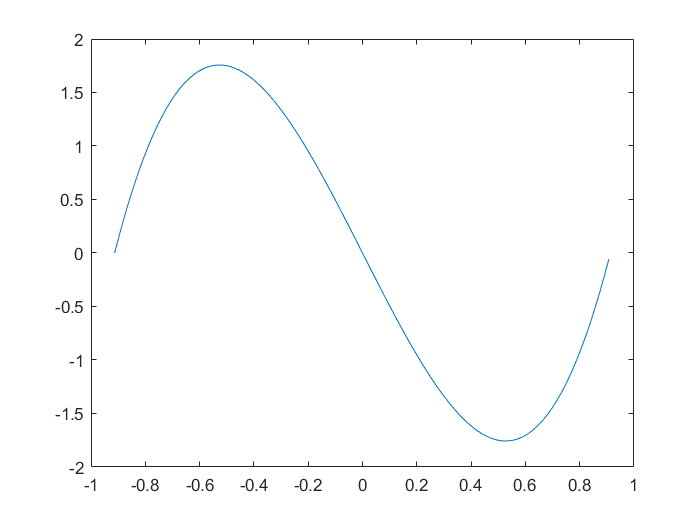

t=-sqrt(5/6):0.01:sqrt(5/6);
figure(),
plot(t, (-5*t+6*(t.^3))),